%	Problem 1
% H-inf state feedback
% Consider the general LTI system
clear global;

A = [-5 1 0; 
	  0 1 1; 
	  1 1 1];
B1 = [0.5;
	  0;
	  0.3];
B2 = [0 0; 
	  0 1; 
	  1 0];
C = [1 0 0; 
	 0 2 1];

% a)
% Implement the H∞ LMI synthesis feasibility problem for a given attenuation level γ as
% a function and design a full state (y = x) feedback control law u = Kx such that the
% closed loop system is stable and the transfer function matrix satisfies
% ‖Gzw‖∞ < 0.5.

K = Hinf_LMI_feasy_p(A, B1, B2, C, 0, 0)


 Solver for LMI feasibility problems L(x) < R(x)
    This solver minimizes  t  subject to  L(x) < R(x) + t*I
    The best value of t should be negative for feasibility

 Iteration   :    Best value of t so far 
 
     1                        0.537490
     2                        0.106422
     3                       -0.048095

 Result:  best value of t:    -0.048095
          f-radius saturation:  0.000% of R =  1.00e+09
 


K =     2.5861  -37.7427  -19.2728
   -3.1922   -2.8125   -0.3311


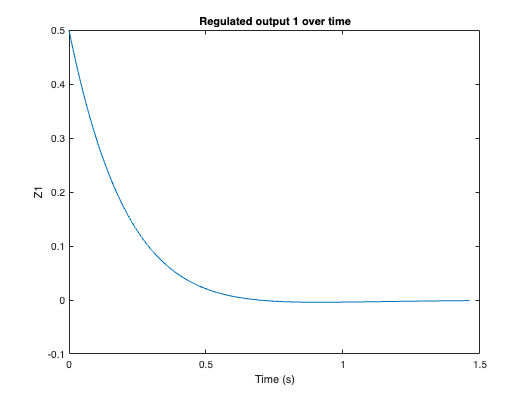


% b)
% Plot the regulated output responses z(t) to an impulse in w (use the subfigure command
% and include one signal per plot).

Awz = A + (B2 * K);
Bwz = B1;
Cwz = C;
Dwz = 0;
sys_wz = ss(Awz, Bwz, Cwz, Dwz);

[Z,T,X] = impulse(sys_wz);
figure();
plot(T, Z(:,1))
title("Regulated output 1 over time");
xlabel("Time (s)");
ylabel("Z1");

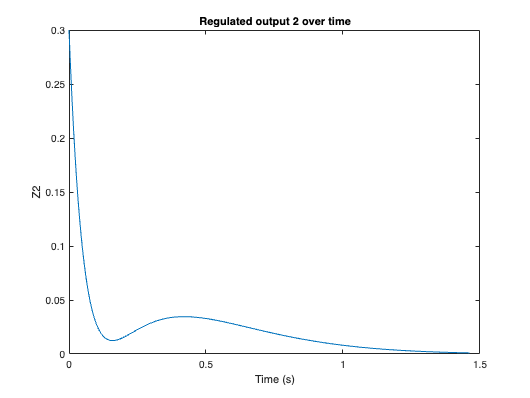


figure();
plot(T, Z(:,2))
title("Regulated output 2 over time");
xlabel("Time (s)");
ylabel("Z2");

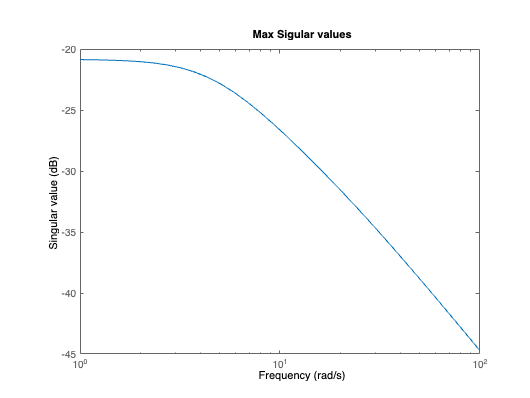


% c)
% Generate a max singular value plot of the closed loop system Gzw(s) using the command
% sigma. Does this system amplify (absolute gain > 1) or attenuate (absolute gain < 1)
% disturbances? Note that the sigma plot generates the gain in dB.

figure()
sigmaplot(sys_wz)
title("Max Sigular values");
xlabel("Frequency");
ylabel("Singular value");

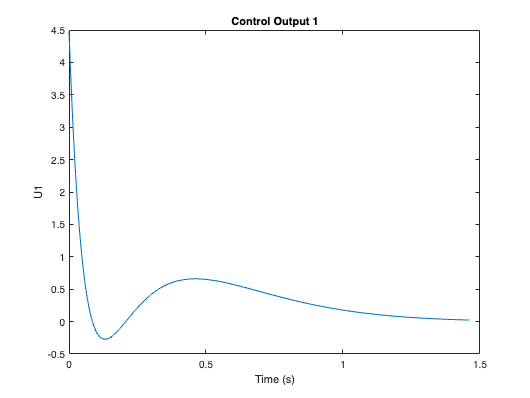


% d) 
% Plot the two control signals u1(t) and u2(t) and compute their L2 norms. Which channel
% requires more input energy?

U = X * -K';
figure()
plot(T, U(:,1))
title("Control Output 1");
xlabel("Time (s)");
ylabel("U1");

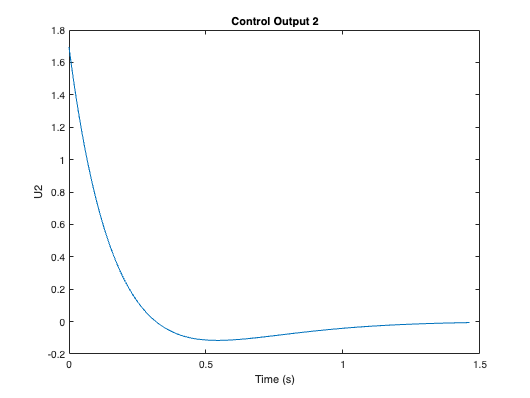


figure()
plot(T, U(:,2))
title("Control Output 2");
xlabel("Time (s)");
ylabel("U2");


fprintf("U1 norm %f", norm(U(:,1)));

U1 norm 10.239400

fprintf("U2 norm %f", norm(U(:,2)));

U2 norm 5.770964

%	Problem 2
% H-2 state feedback
% DC-8 general LTI system
% Define System Dynamics
clear global;

A = [-0.0869  0 0.039 -1 ;         % x1 = delta beta (rad)
     -4.424 -1.184 0 0.335;        % x2 = delta p (rad/s)
     0 1 0 0 ;                     % x3 = delta phi (rad)
     2.148 -0.021 0 -0.228];       % x4 = delta r (rad/s)
B1 = [0 0 0 0.288]';               % w = r_g (yaw rate gust, rad/s)
B2 = [ 0.0223 0.547 0 -1.169]';    % u1 = delta_r
C = eye(4);                       % C = I
D11 = zeros(4,1);               
D12 = [0 0 0 0]';

% a)
% Implement the H2 LMI conditions derived in lecture for the feasibility problem given
% a prescribed attenuation level ‖G(s)‖2 < γ as a function using the LMI Toolbox in
% MATLAB. Design γ for the H2 controller to match the control energy (L2 norm) for an
% equivalent H∞ controller with attenuation level γ = 2.5.
K = H2_LMI_feasy_p(A, B1, B2, C, D11, D12)


 Solver for LMI feasibility problems L(x) < R(x)
    This solver minimizes  t  subject to  L(x) < R(x) + t*I
    The best value of t should be negative for feasibility

 Iteration   :    Best value of t so far 
 
     1                        0.162937
     2                    2.005693e-04
     3                       -0.032009

 Result:  best value of t:    -0.032009
          f-radius saturation:  0.000% of R =  1.00e+09
 


K =   -31.2031    6.0313    7.2953   20.6057


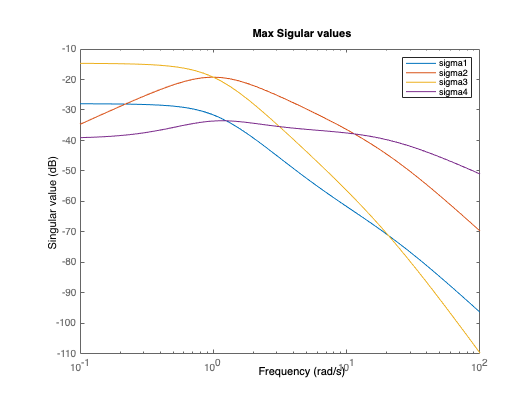


% b)
% Generate the resulting singular value bode plots of the closed loop systems and the
% responses of the state x due to an impulse in the yaw disturbance rg for both the H2
% and H∞ controllers and compare both sets of plots.

Awz = A + (B2 * K);
Bwz = B1;
Cwz = C;
Dwz = 0;
sys_wz = ss(Awz, Bwz, Cwz, Dwz);

figure()
hold on;
sigmaplot(sys_wz(1))
sigmaplot(sys_wz(2))
sigmaplot(sys_wz(3))
sigmaplot(sys_wz(4))
legend("sigma1", "sigma2", "sigma3", "sigma4");
title("Max Sigular values");
xlabel("Frequency");
ylabel("Singular value");


% c) For a white noise yaw disturbance rg of unit intensity, compute the average power in the
% states for each of the closed loop systems and compare.


for i = (1:size(A, 2))
    [Y, T, X] = step(sys_wz(i));
    fprintf("Average power of state %i: %f\n", i, norm(X));
end

Average power of state 1: 1.464463
Average power of state 2: 1.944417
Average power of state 3: 1.720601
Average power of state 4: 5.471670


%	Problem 3
% H-inf observer design
% Consider the generral LTI system

% a)
% Show that for e(t) = x(t) − ˆx(t) and  ̃z(t) = z(t) − ˆz(t), the resulting observation error
% equation is given by
%  ̇e = (A + LC2)e + (B1 + LD21)w
%  ̃z = C1e
% and has closed loop transfer function G ̃zw = C1 [sI − (A + LC2)]−1 (B1 + LD21) from
% w →  ̃z.

% b) Consider the following problem: Given the system in (a) and a positive scalar γ, find a
% matrix L such that ‖G ̃zw‖∞ < γ. Prove that this problem has a solution if and only if
% there exists a matrix W and a positive definite matrix P such that P > 0 and
% |AT P + P A + CT2 W T + W C2,	P B1 + W D21,	CT1|
% |		(P B1 + W D21)T,			−γI,		 0 |	< 0
% |				C1,					 0, 		−γI|
% When such a pair of matrices W and P are found, the solution to the problem is given
% as L = P^−1W .

% c)
% Design an H∞ observer according to the above approach such that ‖G ̃zw‖∞ < 0. For
% the system in Problem 1. Assume that
clear global;

A = [-5 1 0; 
	  0 1 1; 
	  1 1 1];
B1 = [0.5;
	  0;
	  0.3];
B2 = [0 0; 
	  0 1; 
	  1 0];
C = [1 0 0; 
	 0 2 1];
C2 = [1 0 0;
	  0 0 1];

D21 = [0 0]';
% Provide plots of the error states e1(t), e2(t) and e3(t) for 2 seconds for an impulse input
% in w.


## Functions

function k = Hinf_LMI_feasy_p(A, B1, B2, C1, D11, D12)
    % get the input, state sizes
    % needed to define P
    n_states = size(A, 2);
    n_inputs = size(B2, 2);
    
    gamma = 0.5;

    % setup LMI expression (in the heap or sumthin)
    setlmis([])

    W = lmivar(2, [n_inputs n_states]);            % matrix
    X = lmivar(1, [n_states 1]);                   % states

    lmiterm([-1, 1, 1, X], 1, 1);            % 0 < X                        [Condition 1: (1, 1)]

    lmiterm([2, 1, 1, X], A, 1, 's');        % AX + XA' < 0                 [Condition 2: (1, 1)]
    lmiterm([2, 1, 1, W], B2, 1, 's');       % AX + XA'+ W'B2'+ B2W < 0

    lmiterm([2, 1, 2, 0], B1);               % B1 < 0                       [Condition 2: (1, 2)]

    lmiterm([2, 1, 3, X'], 1, C1')           % X'C1' < 0                    [Condition 2: (1, 3)] 
    lmiterm([2, 1, 3, W'], 1, D12')          % X'C1' + W'D12' < 0

    lmiterm([2, 2, 1, 0], B1')               % B1' < 0                      [Condition 2: (2, 1)]

    lmiterm([2, 2, 2, 0], -gamma)            % -gamma < 0                    [Condition 2: (2, 2)]

    lmiterm([2, 2, 3, 0], D11')              % D11' < 0                     [Condition 2: (2, 3)]

    lmiterm([2, 3, 1, X], C1, 1)             % C1X < 0                      [Condition 2: (3, 1)] 
    lmiterm([2, 3, 1, W], D12, 1)            % C1X + D12W < 0

    lmiterm([2, 3, 2, 0], D11)               % D11 < 0                      [Condition 2: (3, 2)]

    lmiterm([2, 3, 3, 0], -gamma)            % -gamma < 0                    [Condition 2: (3, 3)]

    lmi = getlmis;

    [~,xopt] = feasp(lmi);                  % get tmin to check feasibility
    
    w = dec2mat(lmi, xopt, W);
    x = dec2mat(lmi, xopt, X);
    k = w * x^-1;
end

function k = H2_LMI_feasy_p(A, B1, B2, C, D11, D12)
    % get the input, state sizes
    % needed to define P
    n_states = size(A, 2);
    n_inputs = size(B1, 1);
    
    gamma = 2.5;
    I = eye(4);
    % setup LMI expression (in the heap or sumthin)
    setlmis([])

    Z = lmivar(1, [n_states 1]);                   % matrix
    W = lmivar(2, [1 n_inputs]);                   % matrix
    X = lmivar(1, [n_states 1]);                   % states

    lmiterm([-1, 1, 1, X], 1, 1);            % 0 < X                        [Condition 1: (1, 1)]

    lmiterm([2, 1, 1, X], A, 1, 's');        % AX + XA' < 0                 [Condition 2: (1, 1)]
    lmiterm([2, 1, 1, W], B2, 1, 's');       % AX + XA'+ W'B2'+ B2W < 0
    lmiterm([2, 1, 1, 0], B1*B1');           % AX + XA'+ W'B2'+ B2W < 0

    lmiterm([3, 1, 1, Z], -1, 1);            % -Z < 0                       [Condition 3: (1, 2)]

    lmiterm([3, 1, 2, X], C, 1)              % C1X < 0                      [Condition 3: (1, 2)] 
    lmiterm([3, 1, 2, W], D12, 1)            % C1X + D12W < 0

    lmiterm([3, 2, 1, X'], 1, C)             % X'C1' < 0                    [Condition 3: (2, 1)] 
    lmiterm([3, 2, 1, W'], 1, D12)           % X'C1 + W'D12' < 0

    lmiterm([3, 2, 2, X], -1, 1)                % -X < 0                    [Condition 3: (2, 2)]

    for i = (1:n_states)
        lmiterm([4, 1, 1, Z], I(i), I(i)');
    end
    lmiterm([-4, 1, 1, 0], gamma^2);
    
    lmi = getlmis;

    [~,xopt] = feasp(lmi);                  % get tmin to check feasibility
    
    w = dec2mat(lmi, xopt, W);
    x = dec2mat(lmi, xopt, X);
    k = w * x^-1;
end
